## Letter Dataset Analysis

### Initialise

clear;
clc;
clf;
close all;
load letterDatasetClass.mat;

## Dataset Information: attributes not normalised

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min           0   
            Median        4   
            Max          15   

    yBox: 16000×1 double

        Values:

            Min           0   
            Median        7   
            Max          15   

    width

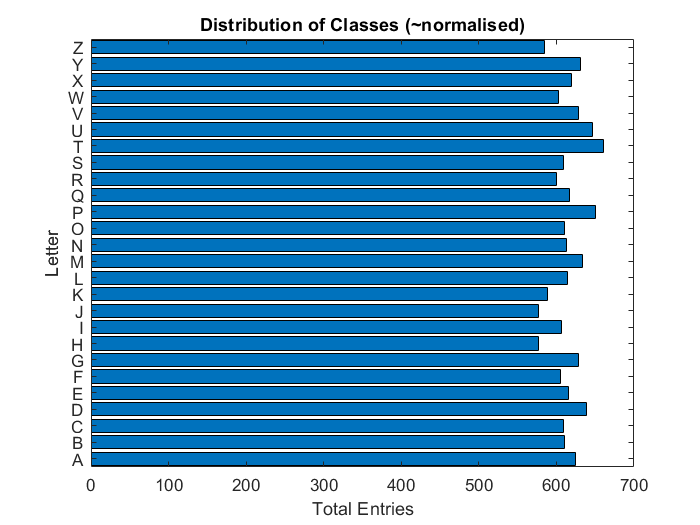

Summary of letter distribution:

Variables:

    Value: 26×1 categorical

        Values:

            A       1    
            B       1    
            C       1    
            D       1    
            E       1    
            F       1    
            G       1    
            H       1    
            I       1    
            J       1    
            K       1    
            L       1    
            M       1    
            N       1    
            O       1    
            P       1    
            Q       1    
            R       1    
            S       1    
            T       1    
            U       1    
            V       1    
            W       1    
            X       1    
            Y       1    
            Z       1    

    Count: 26×1 double

        Values:

            Min          577  
            Median     613.5  
            Max          661  

    Percent: 26×1 double

        Values:

   

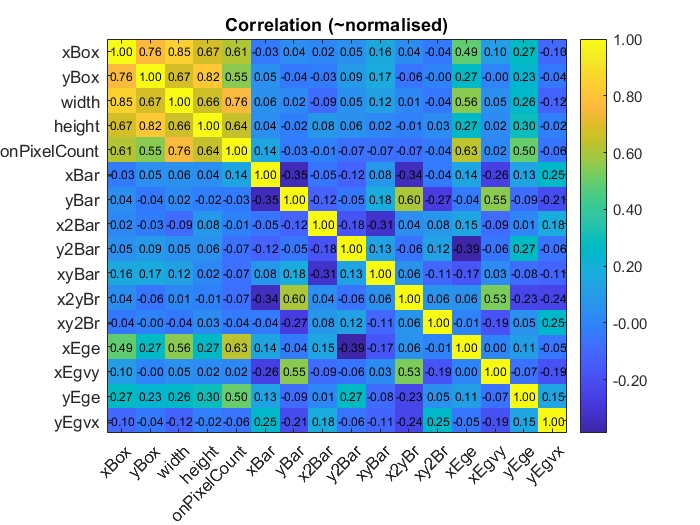

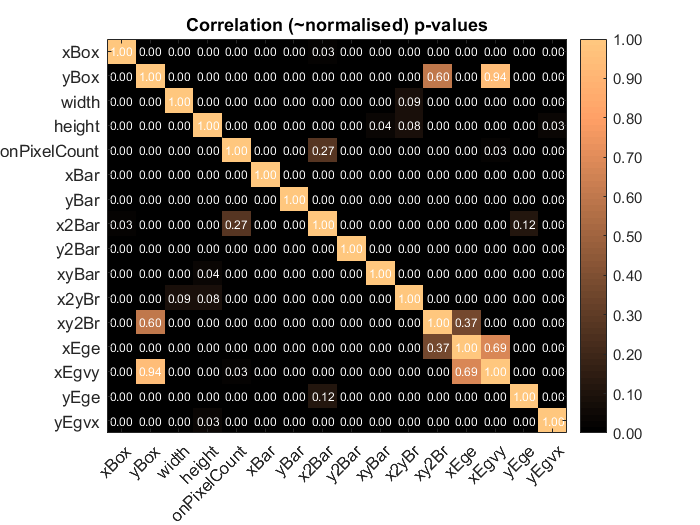

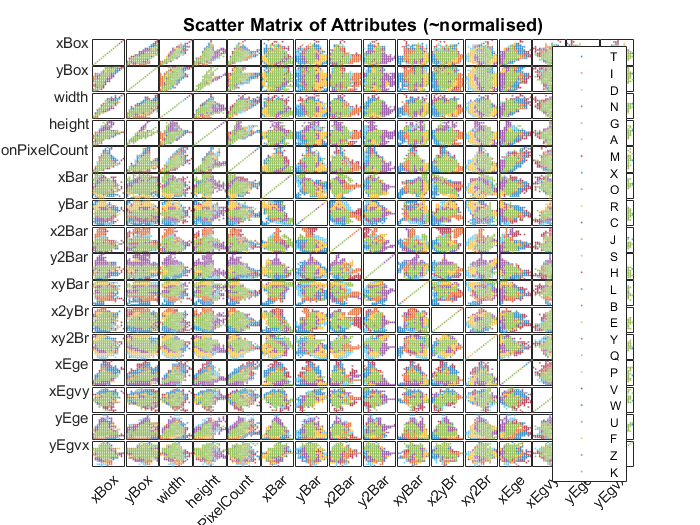

   28.5524
   15.2232
   12.4627
    8.7070
    7.5896
    5.6280
    5.0814
    3.9528
    3.1695
    2.3687
    1.7690
    1.6150
    1.4783
    1.2300
    0.8071
    0.3653



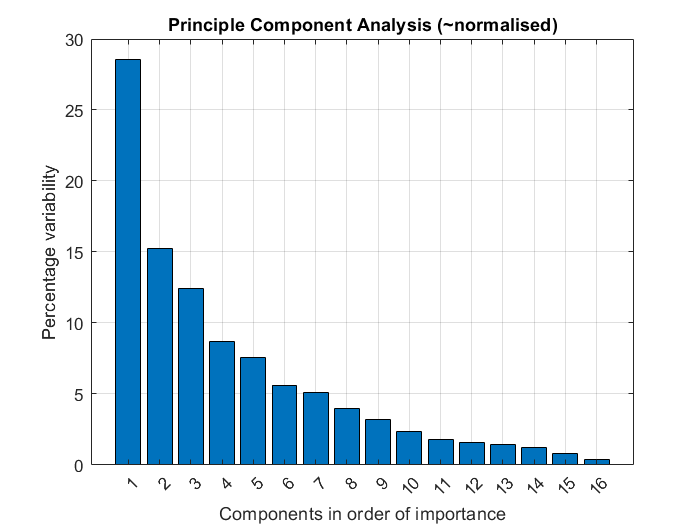

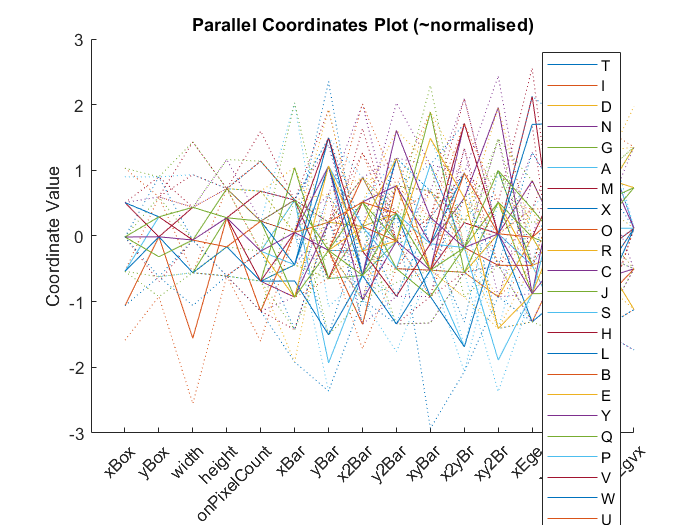

letterDatasetNotNormalised.displayDatasetInformation();

## Dataset Information: attributes normalised

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 1

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min             0 
            Median    0.26667 
            Max             1 

    yBox: 16000×1 double

        Values:

            Min             0 
            Median    0.46667 
            Max             1 

    width

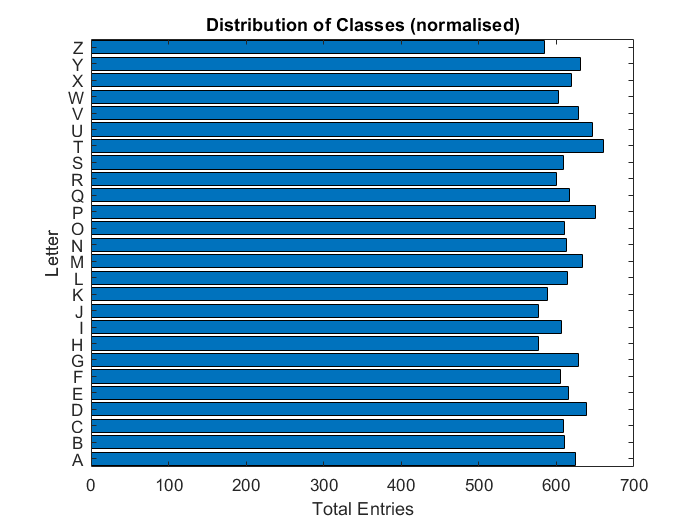

Summary of letter distribution:

Variables:

    Value: 26×1 categorical

        Values:

            A       1    
            B       1    
            C       1    
            D       1    
            E       1    
            F       1    
            G       1    
            H       1    
            I       1    
            J       1    
            K       1    
            L       1    
            M       1    
            N       1    
            O       1    
            P       1    
            Q       1    
            R       1    
            S       1    
            T       1    
            U       1    
            V       1    
            W       1    
            X       1    
            Y       1    
            Z       1    

    Count: 26×1 double

        Values:

            Min          577  
            Median     613.5  
            Max          661  

    Percent: 26×1 double

        Values:

   

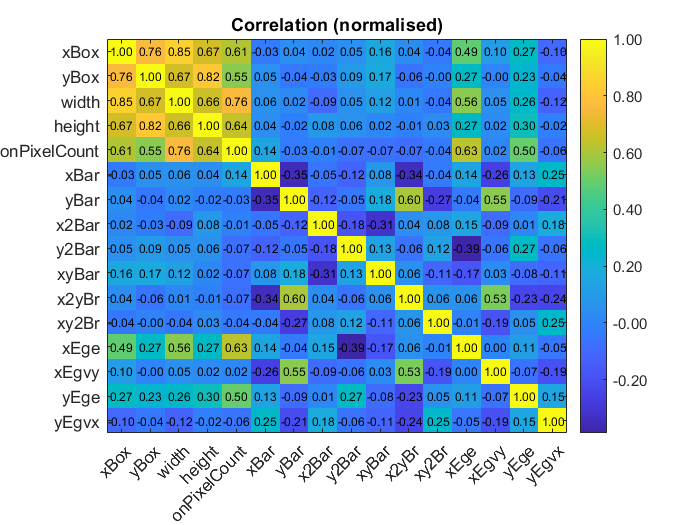

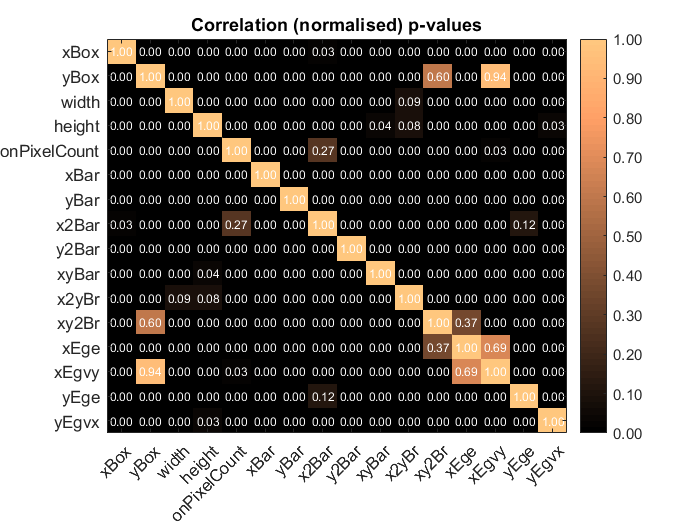

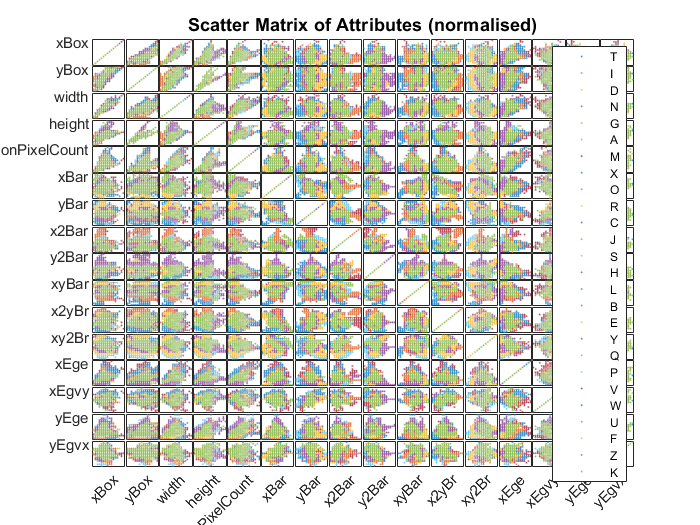

   28.5524
   15.2232
   12.4627
    8.7070
    7.5896
    5.6280
    5.0814
    3.9528
    3.1695
    2.3687
    1.7690
    1.6150
    1.4783
    1.2300
    0.8071
    0.3653



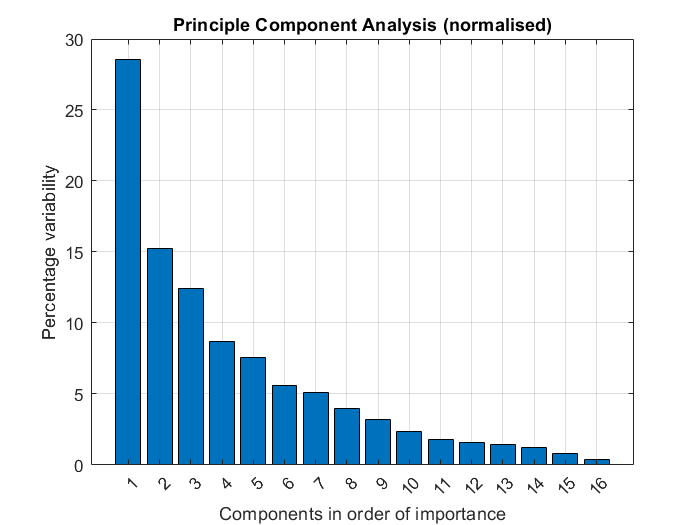

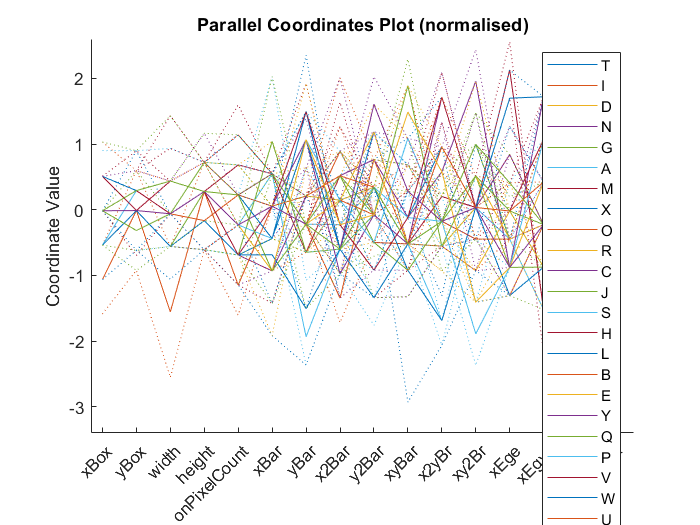

letterDatasetNormalised.displayDatasetInformation();

## Comments

- The dataset distribution of target examples can be treated as balanced (min examples per class 577, max 661).

- There is some strong correlation between attributes which are highly likely to be associated. The scatter matrix confirms this by showing a tendency to plot in a linear grouping.

- Additional correlated attributes are shown on the p-value correlation.

- The PCA shows that there is no set of components which are predominant.

- The parallel coordinates' classes display greater volatility for the attributes that are highly correlated.